# Identifying Candidate Genes in Breast Cancer Using Solution Concepts from Coalitional Game Theory

Nicolas Thiel

Department of Advanced Computing Sciences

Faculty of Science and Engineering

Maastricht University

Maastricht, The Netherlands

# Main

## Data

### Read data

T_data = readtable('data/GSE183947.csv', VariableNamingRule='preserve');
data = table2array(T_data(:,2:end));

is_tumor = [true(1, 30), false(1, 30)]; % see GSE183947 on GEO

### Filtering

threshold_initial = 1; % minimum 1 FPKM
min_samples = size(data, 2) / 2; % in half the samples
sufficient_counts = sum(data >= threshold_initial, 2) >= min_samples;
filtered_data = data(sufficient_counts, :);
original_indices = find(sufficient_counts);

### Transformation to TPM

fpkm_sum = sum(filtered_data, 1);
tpm_data = zeros(size(filtered_data));
for i = 1:size(filtered_data, 2)
    tpm_data(:, i) = filtered_data(:, i) ./ fpkm_sum(i) * 1e6;
end

### log2 transformation

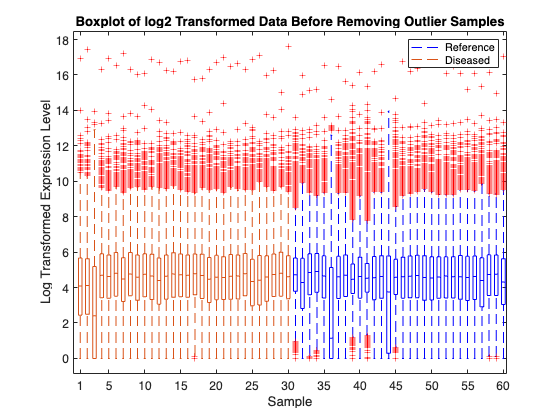

log_data = log2(tpm_data + 1); % +1 to avoid division by 0

figure;
hold on;
h1 = boxplot(log_data(:, ~is_tumor), 'Colors', 'b', 'Positions', find(~is_tumor));
h2 = boxplot(log_data(:, is_tumor), 'Colors', [0.8500, 0.3250, 0.0980], 'Positions', find(is_tumor));
hold off;
title('Boxplot of log2 Transformed Data Before Removing Outlier Samples');
xlabel('Sample');
ylabel('Log Transformed Expression Level');
set(gca, 'FontSize', 12);
xticks([1 5 10 15 20 25 30 35 40 45 50 55 60])
xticklabels({'1', '5', '10', '15', '20', '25', '30', '35', '40', '45', '50', '55', '60'})
set(gca, 'XTick', xticks, 'XTickLabel', xticklabels);
legend([h1(1), h2(1)], {'Reference', 'Diseased'}, 'Location', 'NorthEast');
saveas(gcf, 'figs/boxplot_log_transformed_data_before_removing_outlier_samples.png')

### Removing Outlier Samples

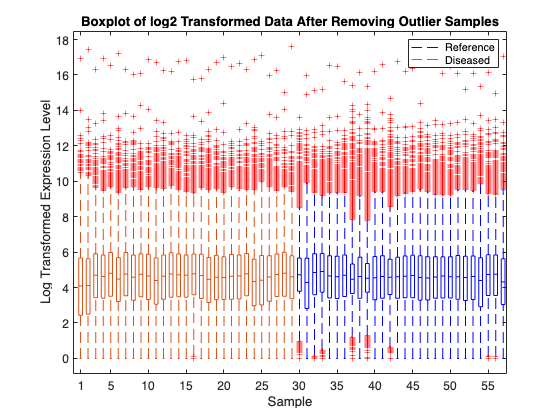

log_data(:, [3, 36, 44]) = [];
is_tumor([3, 36, 44]) = [];

figure;
hold on;
h1 = boxplot(log_data(:, ~is_tumor), 'Colors', 'b', 'Positions', find(~is_tumor));
h2 = boxplot(log_data(:, is_tumor), 'Colors', [0.8500, 0.3250, 0.0980], 'Positions', find(is_tumor));
hold off;
title('Boxplot of log2 Transformed Data After Removing Outlier Samples');
xlabel('Sample');
ylabel('Log Transformed Expression Level');
set(gca, 'FontSize', 12);
xticks([1 5 10 15 20 25 30 35 40 45 50 55 60])
xticklabels({'1', '5', '10', '15', '20', '25', '30', '35', '40', '45', '50', '55', '60'})
set(gca, 'XTick', xticks, 'XTickLabel', xticklabels);
legend([h1(1), h2(1)], {'Reference', 'Diseased'}, 'Location', 'NorthEast');
saveas(gcf, 'figs/boxplot_log_transformed_data_after_removing_outlier_samples.png')

### Quantile normalization

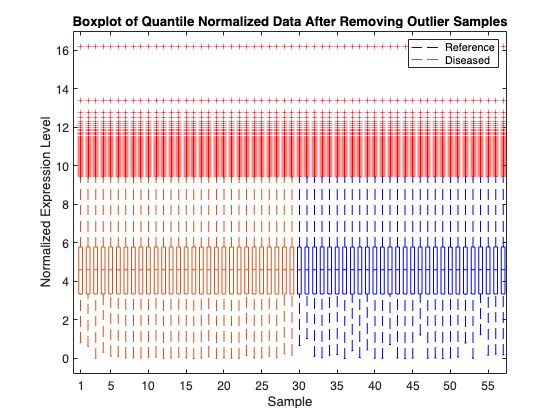

normalized_data = quantilenorm(log_data);

figure;
hold on;
h1 = boxplot(normalized_data(:, ~is_tumor), 'Colors', 'b', 'Positions', find(~is_tumor));
h2 = boxplot(normalized_data(:, is_tumor), 'Colors', [0.8500, 0.3250, 0.0980], 'Positions', find(is_tumor));
hold off;
title('Boxplot of Quantile Normalized Data After Removing Outlier Samples');
xlabel('Sample');
ylabel('Normalized Expression Level');
set(gca, 'FontSize', 12);
xticks([1 5 10 15 20 25 30 35 40 45 50 55 60])
xticklabels({'1', '5', '10', '15', '20', '25', '30', '35', '40', '45', '50', '55', '60'})
set(gca, 'XTick', xticks, 'XTickLabel', xticklabels);
legend([h1(1), h2(1)], {'Reference', 'Diseased'}, 'Location', 'NorthEast');
saveas(gcf, 'figs/boxplot_quantilenorm_data_after_removing_outlier_samples.png')

### Estimate Distribution

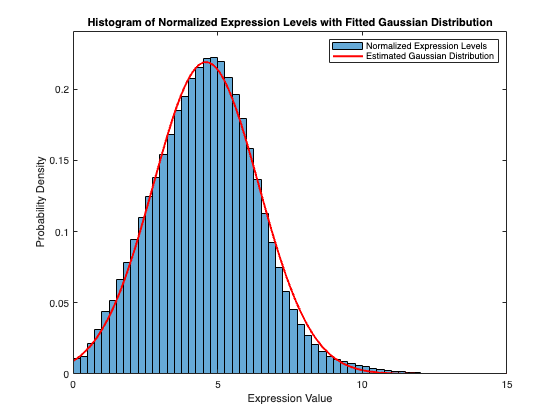

% update data
data = normalized_data;
n = size(data, 1);

figure;
expr_values = data(:);
histogram(expr_values, 'Normalization', 'pdf', 'BinWidth', 0.25);
[counts, edges] = histcounts(expr_values);
mu = mean(expr_values);
sigma = std(expr_values);
hold on;
x = linspace(min(edges), max(edges), 1000);
y = normpdf(x, mu, sigma);
plot(x, y, 'r', 'LineWidth', 2);
xlabel('Expression Value');
ylabel('Probability Density');
legend('Normalized Expression Levels', 'Estimated Gaussian Distribution');
title('Histogram of Normalized Expression Levels with Fitted Gaussian Distribution');
xlim([0, 15]);
ylim([0, max(y)*1.1]);
hold off;
saveas(gcf, 'figs/histogram_quantilenorm_data.png');

## Coalitional Game

### Definition of Key Variables

N = 1:size(data,1); % players
samples = 1:size(data,2); % samples

% reference samples
SR = samples(:,~is_tumor); 
A_SR = data(:,~is_tumor);
num_SR = length(SR);

% disease samples
SD = samples(:,is_tumor);
A_SD = data(:,is_tumor);
num_SD = length(SD);

### Identifiying differentially expressed genes

B = boolean_expression_matrix(A_SD, A_SR, 0, 100); % see equation (8)
sp_B = support_of(B); % see equation (7) 

### Coalitions

[coalitions, num_coalitions] = find_coalitions(sp_B);

### Characteristic function

% see equations (9), (10)
theta_T = cell(1,num_coalitions);
for i = 1:num_coalitions
    for j = 1:length(SD)
        if all(ismember(sp_B{j}, coalitions{i})) && ~isempty(sp_B{j})
            theta_T{i}(end+1) = j;
        end
    end
end
v = cellfun(@(x) length(x) / num_SD, theta_T);

### Unanimity coefficients

% see equations (11), (12)
lambda_bar = zeros(1,num_coalitions);
for j = 1:num_coalitions
    S = coalitions{j};
    for k = 1:length(SD)
        if isequal(sp_B{k}, S)
            lambda_bar(j) = lambda_bar(j) + 1;
        end
    end
end
lambda = lambda_bar / num_SD;

## Power Values

### Shapley Value

% see equation (4)
shapley_value = zeros(1,n);
for i = 1:n
    for j = 1:num_coalitions
        S = sp_B{j};
        if ismember(i, S)
            shapley_value(i) = shapley_value(i) + (lambda(j) / length(S));
        end
    end
end

### Banzhaf Index

% see equation (6)
% since Banzhaf values are very small, vpa is used
digits(100);
banzhaf_index = vpa(zeros(1, n), 100);
for i = 1:n
    for j = 1:num_coalitions
        S = sp_B{j};
        if ismember(i, S)
            lambda_vpa = vpa(lambda(j), 100);
            len_S_minus_1 = vpa(length(S) - 1, 100);
            two_vpa = vpa(2, 100);
            denom_vpa = vpa(two_vpa^len_S_minus_1, 100);
            term_vpa = lambda_vpa / denom_vpa;
            banzhaf_index(i) = banzhaf_index(i) + term_vpa; 
        end
    end
end

## Results

### Table

genes = T_data.Var1(original_indices);
min_non_zero_value = min(banzhaf_index(banzhaf_index > 0));
epsilon = min_non_zero_value * vpa('1e-10');
log_banzhaf_index = vpa(log10(banzhaf_index + epsilon)); % log10 transformation for better plot scale
backup = log_banzhaf_index;
log_banzhaf_index = double(log_banzhaf_index);

T_results = table(transpose(1:length(genes)), genes, transpose(shapley_value), transpose(log_banzhaf_index),transpose(banzhaf_index), VariableNames={'Player', 'Gene', 'Shapley', 'log10(Banzhaf)', 'Banzhaf'})

T_results = 15076×5 table
    Player        Gene         Shapley      log10(Banzhaf)                         Banzhaf                      
    ______    ____________    __________    ______________    __________________________________________________

       1      {'TSPAN6'  }    0.00010851       -384.07        8.48159465472112908920057540218989452752854438386…
       2      {'DPM1'    }             0       -830.87        0                                                 
       3      {'SCYL3'   }    0.00024843        -304.6        2.51418000674358534210692226488097297849431962923…
       4      {'C1orf112'}             0       -830.87        0                                                 
       5      {'FGR'     }             0       -830.87        0                                                 
       6    

% sort and rank according to Shapley value (see experiment 1)
sorted_by_shapley = sortrows(T_results, 'Shapley', 'descend');
[unique_values, ~, ~] = unique(sorted_by_shapley.Shapley, 'stable');
ranks = arrayfun(@(x) find(unique_values == x, 1), sorted_by_shapley.Shapley);
rank_table = array2table(ranks, 'VariableNames', {'Rank'});
sorted_by_shapley = [rank_table, sorted_by_shapley];

% sort and rank according to Banzhaf index (see experiment 2)
sorted_by_banzhaf = sortrows(T_results, 'log10(Banzhaf)', 'descend');
[unique_values, ~, ~] = unique(sorted_by_banzhaf.('log10(Banzhaf)'), 'stable');
ranks = arrayfun(@(x) find(unique_values == x, 1), sorted_by_banzhaf.('log10(Banzhaf)'));
rank_table = array2table(ranks, 'VariableNames', {'Rank'});
sorted_by_banzhaf = [rank_table, sorted_by_banzhaf];

### Plots

#### Lineplot - Shapley Value in Descending Order

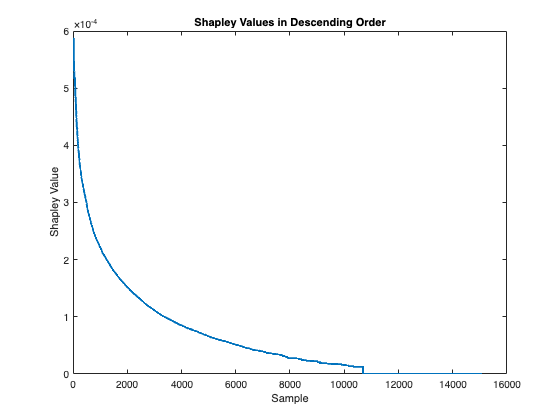

figure;
plot(sorted_by_shapley.Shapley, 'LineWidth', 2);
title('Shapley Values in Descending Order');
xlabel('Sample');
ylabel('Shapley Value');
saveas(gcf, 'figs/lineplot_shapley_desc.png');

#### Lineplot - Banzhaf Index in Descending Order

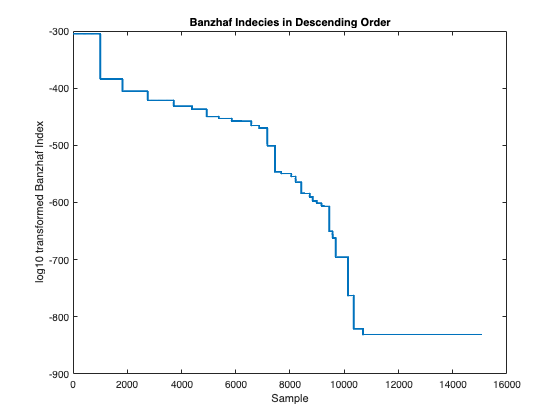

figure;
figure;
plot(sorted_by_banzhaf.('log10(Banzhaf)'), 'LineWidth', 2);
title('Banzhaf Indecies in Descending Order');
xlabel('Sample')
ylabel('log10 transformed Banzhaf Index');
saveas(gcf, 'figs/lineplot_banzhaf_desc.png');

#### Scatterplot - Shapley Value and Banzhaf Index per Gene

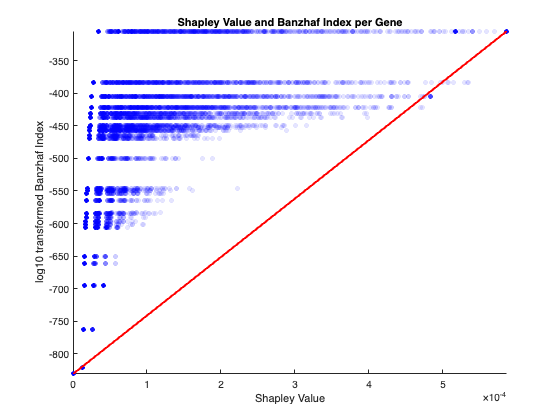

figure;
scatter(T_results.Shapley, T_results.('log10(Banzhaf)'), 20, 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'b', 'MarkerFaceAlpha', 0.1, 'MarkerEdgeAlpha', 0.1);
hold on;
min_shapley = min(T_results.Shapley);
max_shapley = max(T_results.Shapley);
min_banzhaf = min(T_results.('log10(Banzhaf)'));
max_banzhaf = max(T_results.('log10(Banzhaf)'));
plot([min_shapley, max_shapley], [min_banzhaf, max_banzhaf], 'r', 'LineWidth', 2);
title('Shapley Value and Banzhaf Index per Gene');
xlabel('Shapley Value');
ylabel('log10 transformed Banzhaf Index');
xlim([min_shapley, max_shapley]);
ylim([min_banzhaf, max_banzhaf]);
hold off;
saveas(gcf, 'figs/scatter_shapley_banzhaf.png');

#### Barplot - Common and Unique Players Across Percentiles

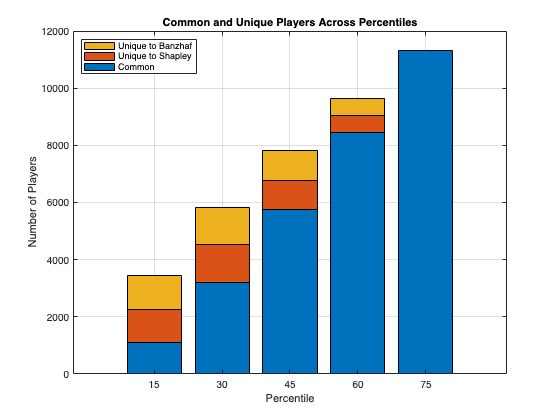

percentiles = [0.15, 0.30, 0.45, 0.60, 0.75];
num_percentiles = length(percentiles);
common_players_count = zeros(1, num_percentiles);
unique_players_count = zeros(1, num_percentiles);
unique_shapley_count = zeros(1, num_percentiles);
unique_banzhaf_count = zeros(1, num_percentiles);

% find common players across percentiles
for p = 1:num_percentiles
    percentile = percentiles(p);
    top_percentile_count = round(percentile * n);
    top_shapley_indices = sorted_by_shapley.Player(1:top_percentile_count);
    top_banzhaf_indices = sorted_by_banzhaf.Player(1:top_percentile_count);
    common_indices = intersect(top_shapley_indices, top_banzhaf_indices);
    unique_indices_shapley = setdiff(top_shapley_indices, common_indices);
    unique_indices_banzhaf = setdiff(top_banzhaf_indices, common_indices);
    common_players_count(p) = length(common_indices);
    unique_shapley_count(p) = length(unique_indices_shapley);
    unique_banzhaf_count(p) = length(unique_indices_banzhaf);
    unique_players_count(p) = length(unique_indices_shapley);
end

figure;
bar_data = [common_players_count' unique_shapley_count', unique_banzhaf_count'];
bar(bar_data, 'stacked');
set(gca, 'XTickLabel', {'15', '30', '45', '60', '75'});
xlabel('Percentile');
ylabel('Number of Players');
title('Common and Unique Players Across Percentiles');
legend({'Common', 'Unique to Shapley', 'Unique to Banzhaf'}, 'Location', 'NorthWest');
grid on;
saveas(gcf, 'figs/stacked_barplot_common_players.png');

#### Heatmap - Common Players Ratio Across Percentiles

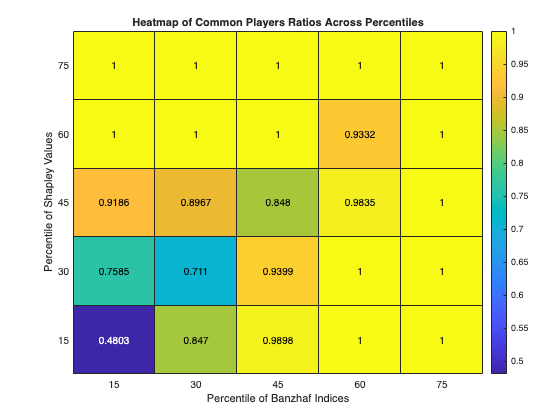

common_players_ratio_matrix = zeros(num_percentiles, num_percentiles);
% find common players ration across percentiles
for i = 1:num_percentiles
    for j = 1:num_percentiles
        if i == j
            common_players_ratio_matrix(i, j) = common_players_count(i) / (common_players_count(i) + unique_players_count(i));
        else
            top_shapley = sorted_by_shapley.Player(1:round(percentiles(i) * n));
            top_banzhaf = sorted_by_banzhaf.Player(1:round(percentiles(j) * n));
            common_players = intersect(top_shapley, top_banzhaf);
            common_players_ratio_matrix(i, j) = length(common_players) / min(length(top_shapley), length(top_banzhaf));
        end
    end
end
common_players_ratio_matrix = flipud(common_players_ratio_matrix);

figure;
heatmap(100 * percentiles, 100 * fliplr(percentiles), common_players_ratio_matrix, 'Colormap', parula, 'ColorbarVisible', 'on');
xlabel('Percentile of Banzhaf Indices');
ylabel('Percentile of Shapley Values');
title('Heatmap of Common Players Ratios Across Percentiles');
saveas(gcf, 'figs/heatmap_common_players_ratios.png');